clear 

sympoly x y
f = (1+ x^0.30*y) * (1+ x^0.10*y) * (1+ x^0.20*y) * (1+ x^0.20*y);

Pn = sympoly2polyn(f)

Pn = struct with fields:
      ModelTerms: [11×3 double]
    Coefficients: [1 1 2 1 2 2 2 1 2 1 1]
        VarNames: {''  'x'  'y'}



syms x y
f = (1+ x^0.30*y) * (1+ x^0.30*y) * (1+ x^0.10*y) 

$$f = \left(x^{1/10}\,y+1\right)\,{\left(x^{3/10}\,y+1\right)}^{2}$$

fexp = expand(f)

$$fexp = 2\,x^{2/5}\,y^{2}+x^{3/5}\,y^{2}+x^{7/10}\,y^{3}+x^{1/10}\,y+2\,x^{3/10}\,y+1$$

W = [0, 0.4, 0.4,0.2;  % test incloseness
     0, 0, 0,0;
     0, 0, 0,0;
     0.4,   0.3, 0.3,0];
 
G = digraph(W)

G =   digraph with properties:

    Edges: [6×2 table]
    Nodes: [4×0 table]


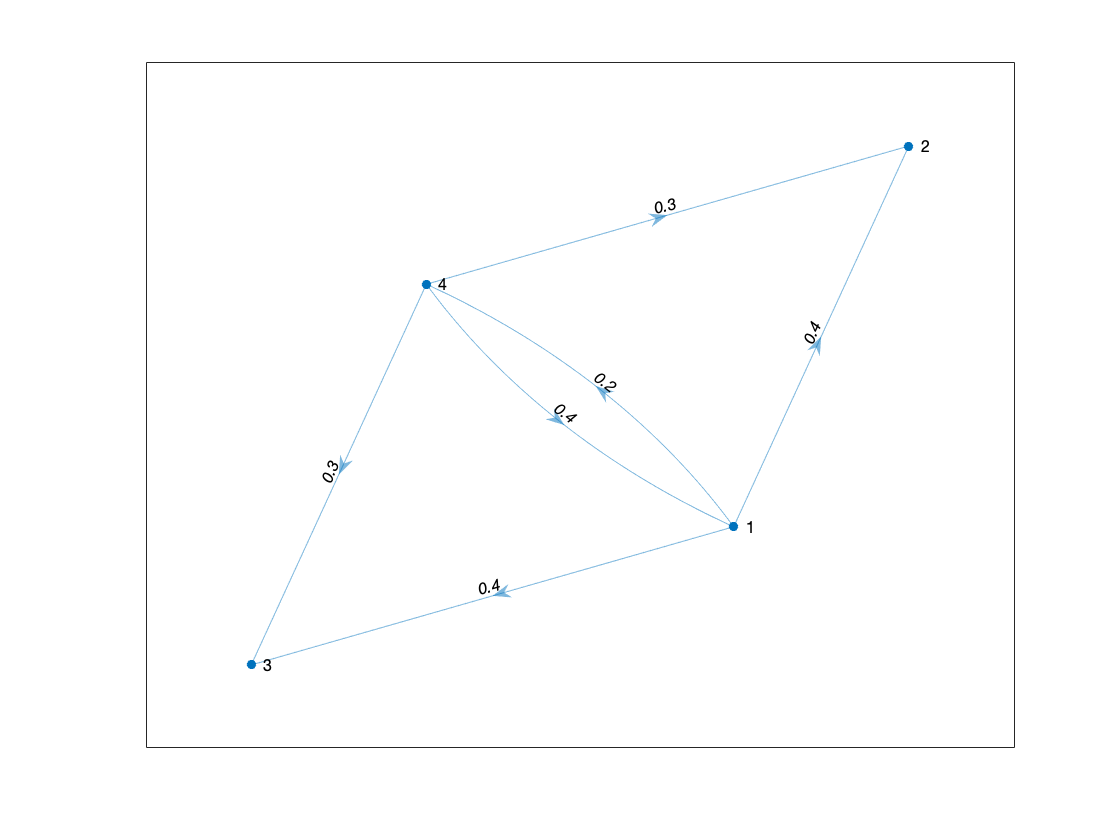

plot(G,'Layout','force','EdgeLabel',G.Edges.Weight)

P = zeros(5,1);
x =[0.5; 0.4; 0.5; 0.5;0.3]

x =     0.5000
    0.4000
    0.5000
    0.5000
    0.3000


[x_s,I] = sort(x); 
J = find(x_s == 0.5);


x_0 = rand(5,1);
[x_s,I] = sort(x_0);
x_0([I(5) 4]) = x_0([4 I(5)]);